# Honours Live Script 12

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
 end

## Save Data

 if exist("workspaceVarHonours", 'var')
     clearVarsArray = clearVars();
     clear(clearVarsArray{:})
     clear clearVarsArray
     save matlabHonours.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Expected Value - Variance Trade-off

Verifying Chapter 3 Work

Looking at Correlations on a Smaller Scale

Proportional Overlap Between Simulations

Spatial Spread of Solutions

Patterns in Solutions

## Assumptions / Notes

## Expected Value - Variance Trade-off

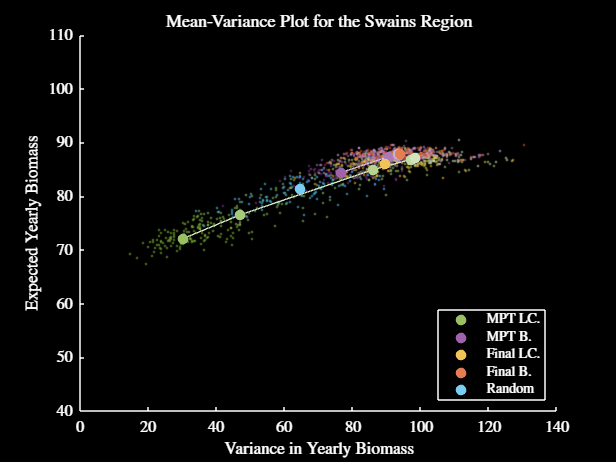

% gonna make a fun little plot of the good old main results in 2-D space,
% probably with just their median values mainly, and then maybe the rest of
% the points in the background but very faint
figure
plotFinalResults(simOutCellSwains, "Swains")
setFontSize(13)
ylim([40, 110])
% figResize(1.2)
saveFig("meanVarSpaceSwains")
darkFig()
saveFig("meanVarSpaceSwainsDM")

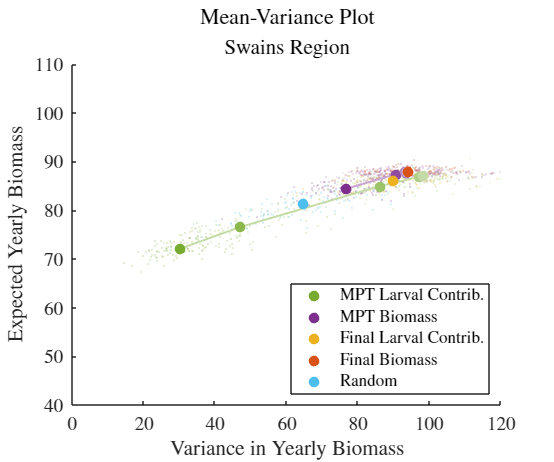

figure
plotFinalResults(simOutCellSwains, "Swains", "pres")
setFontSize(16)
ylim([40, 110])
xlim([0, 120])
figResize(1, 0.9)
saveFig("meanVarSpaceSwainsPP")

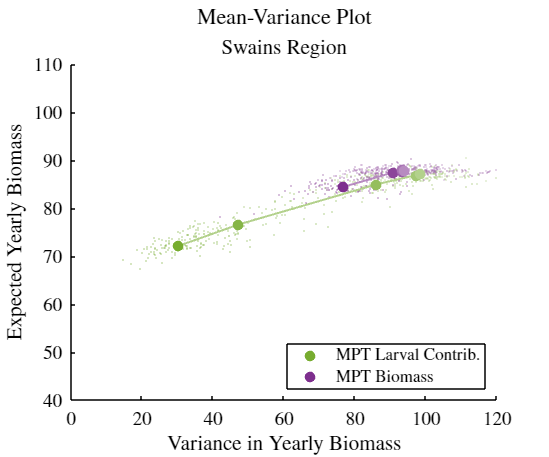

figure
plotFinalResults(simOutCellSwains([1, 5:14]), "Swains", "pres")
setFontSize(16)
ylim([40, 110])
xlim([0, 120])
figResize(1, 0.9)
set(gca, "color", 'w')
var1 = gca;
var1.Legend.Color = 'w';
var1.Legend.TextColor = 'k';
var1.Legend.EdgeColor = 'k';
var1.XColor = 'k';
var1.YColor = 'k';
var1.Title.Color = 'k';
var1.Subtitle.Color = 'k';
saveFig("meanVarSpaceSwainsPP2")

figure
plotFinalResults(simOutCellNorth, "Northern GBR", "pres")
fig = gcf;
fig.Children(1).Location = "northwest"

fig =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [1 1 1]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


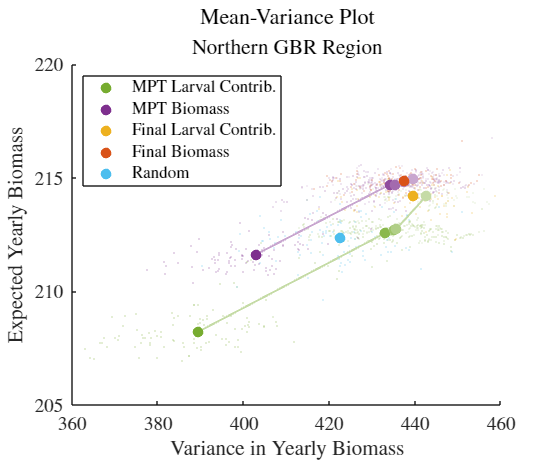

setFontSize(16)
ylim([205, 220])
xlim([360, 460])
figResize(1, 0.9)
saveFig("meanVarSpaceNorthPP")

figure
plotFinalResults(simOutCellNorth([1, 5:14]), "Northern GBR", "pres")
fig = gcf;
fig.Children(1).Location = "northwest"

fig =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [1 1 1]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


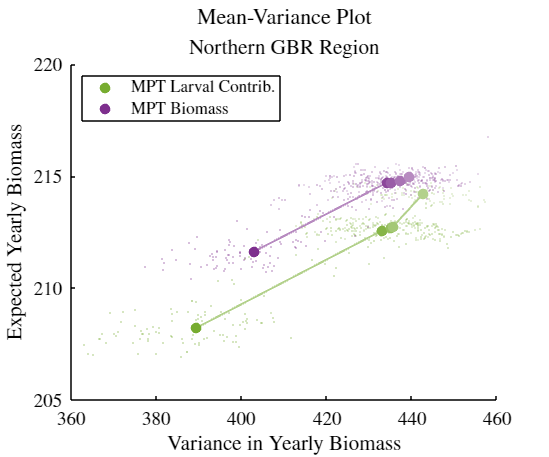

setFontSize(16)
ylim([205, 220])
xlim([360, 460])
figResize(1, 0.9)
set(gca, "color", 'w')
var1 = gca;
var1.Legend.Color = 'w';
var1.Legend.TextColor = 'k';
var1.Legend.EdgeColor = 'k';
var1.XColor = 'k';
var1.YColor = 'k';
var1.Title.Color = 'k';
var1.Subtitle.Color = 'k';
saveFig("meanVarSpaceNorthPP2")

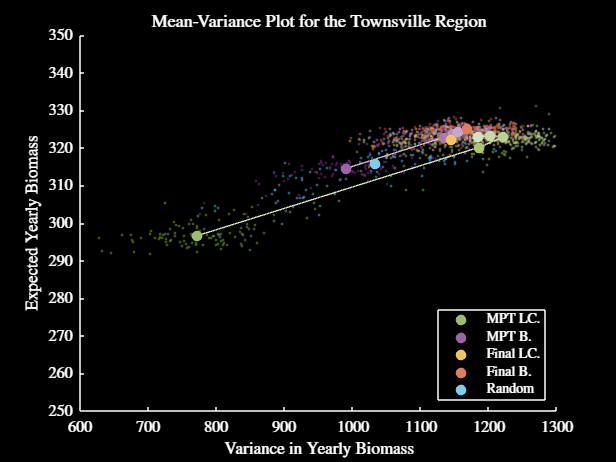

figure
plotFinalResults(simOutCellTowns, "Townsville")
axis([600, 1300, 290, 335])
ylim([250, 350])
setFontSize(13)
saveFig("meanVarSpaceTowns")
darkFig()
saveFig("meanVarSpaceTownsDM")

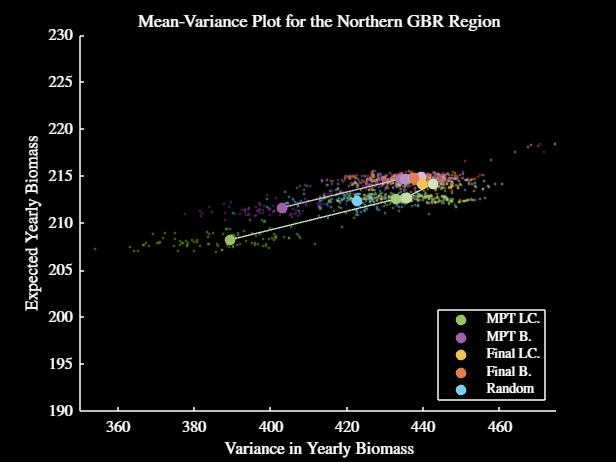

figure
plotFinalResults(simOutCellNorth, "Northern GBR")
axis([350, 475, 206, 217])
setFontSize(13)
ylim([190, 230])
saveFig("meanVarSpaceNorth")
darkFig()
saveFig("meanVarSpaceNorthDM")

% saveCoolFig("meanVarianceSpaceNorthernGBR", 'none')

## Verifying Chapter 3 Work

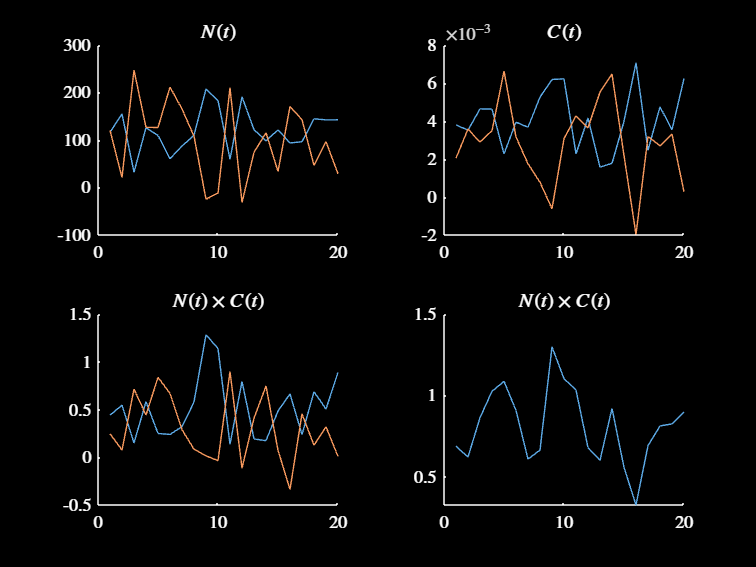

% because I'm now paranoid, let's make sure that the work I presented in
% chapter 3 actually makes sense - that is, that my variance calculation is
% correct
n1Hat = 100;
n2Hat = 130;
n1Std = 30;
n2Std = 50;
c1Hat = 0.004;
c2Hat = 0.003;
c1Std = 0.002;
c2Std = 0.0025;

% set the correlations
corrC = -0.9;
corrN = -0.9;

% run sim
figure
var1 = sim3ReefSystem(c1Hat, c2Hat, c1Std, c2Std, n1Hat, ...
    n2Hat, n1Std, n2Std, corrC, corrN);
darkFig()

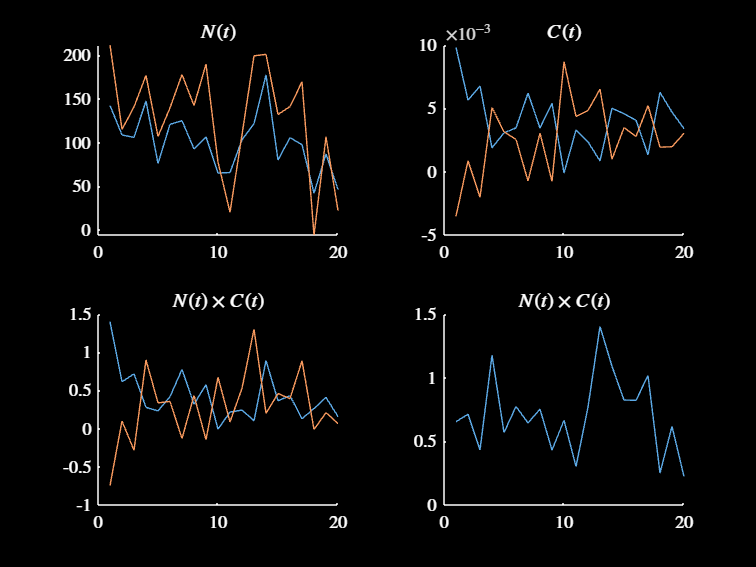


% run sim, but with one correlation larger
figure
var2 = sim3ReefSystem(c1Hat, c2Hat, c1Std, c2Std, n1Hat, ...
    n2Hat, n1Std, n2Std, corrC, 0.8);
darkFig()


var1

var1 = 0.0534

var2

var2 = 0.0934

% run the simulations on the system, and check that the variance of the
% system matches the variance I calculated (approximately), and using the
% cases that I showed in the other figure

% setup parameters for the simulation
nReps = 500;
simVar = cell(6, 1);
for i = 1:length(simVar)
    simVar{i} = zeros(1, nReps);
end
theorVar = zeros(6, 1);

% do a bunch of reps
for r = 1:nReps

    % case of both CVs below 1
    [simVar{1}(r), theorVar(1)] = sim3ReefSystem(0.007, 0.008, 0.003, ...
        0.002, 100, 120, 20, 30, -0.5, 0.5, "no");

    % do a case for both CVs equal to 1
    [simVar{2}(r), theorVar(2)] = sim3ReefSystem(0.007, 0.008, 0.007, ...
        0.008, 70, 80, 70, 80, 0.2, -0.9, "no");

    % do a case CVc > CVn
    [simVar{3}(r), theorVar(3)] = sim3ReefSystem(0.003, 0.002, 0.009, ...
        0.008, 80, 100, 100, 120, -0.34, 0.5, "no");

    % do a case CVc < CVn
    [simVar{4}(r), theorVar(4)] = sim3ReefSystem(0.003, 0.002, 0.001, ...
        0.005, 90, 80, 100, 120, -0.3, 0.8, "no");

    % do a case CVc > CVn but CVc == 1
    [simVar{5}(r), theorVar(5)] = sim3ReefSystem(0.003, 0.002, 0.003, ...
        0.002, 80, 100, 70, 80, 0.1, -0.6, "no");

    % do a case CVc < CVn but CVn == 1
    [simVar{6}(r), theorVar(6)] = sim3ReefSystem(0.003, 0.002, 0.001, ...
        0.0008, 90, 80, 90, 80, -0.5, -0.2, "no");

end

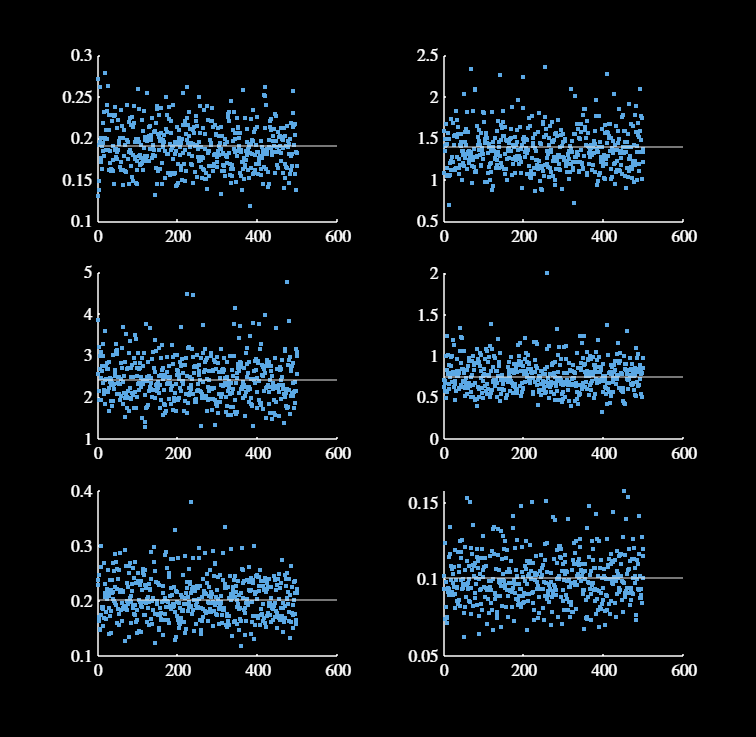

% plot the results
figure
tiledlayout(3, 2)
for i = 1:6
    nexttile
    hold on
    plot(simVar{i}, '.')
    yline(theorVar(i))
end
figResize(1.3)
darkFig()


% alright, that seems reasonable I trust my results now xd

## Looking at Correlations on a Smaller Scale

% wanna quickly look at correlations on a smaller spatial scale, i.e. each
% study area
corrMatSwains = calcLarvalCorr(areaStructSwains.conMats); 

% calculate the autocorrelations for the coral data
corrMatTowns = calcLarvalCorr(areaStructTowns.conMats);

% calculate the autocorrelations for the SLIM data
corrMatNorth = calcLarvalCorr(areaStructNorth.conMats);

% calculate the correlations across the entire reef system
corrMatCT = calcLarvalCorr(conMatsCT);

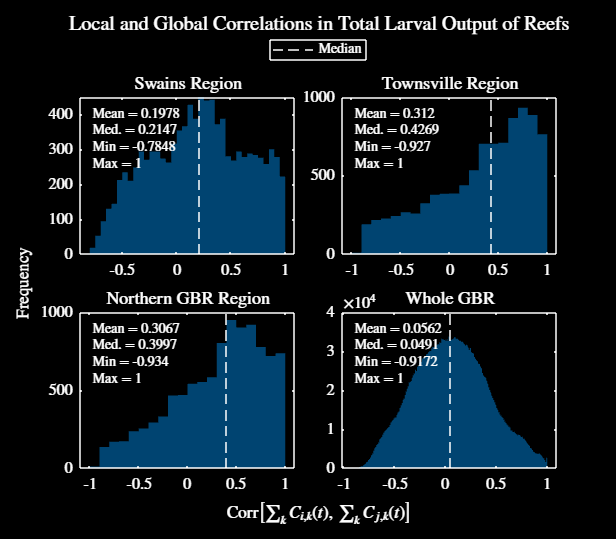

% do a nice big figure of them :)
figure
plotConnectivityStats({corrMatSwains(:), corrMatTowns(:), corrMatNorth(:), ...
    corrMatCT(:)}, "correlationLoc", ["Swains Region", "Townsville Region", ...
    "Northern GBR Region", "Whole GBR"])
setFontSize(13)
figResize(1.4, 1.2)
saveFig("connectivityCorrLoc")
darkFig()
saveFig("connectivityCorrLocDM")

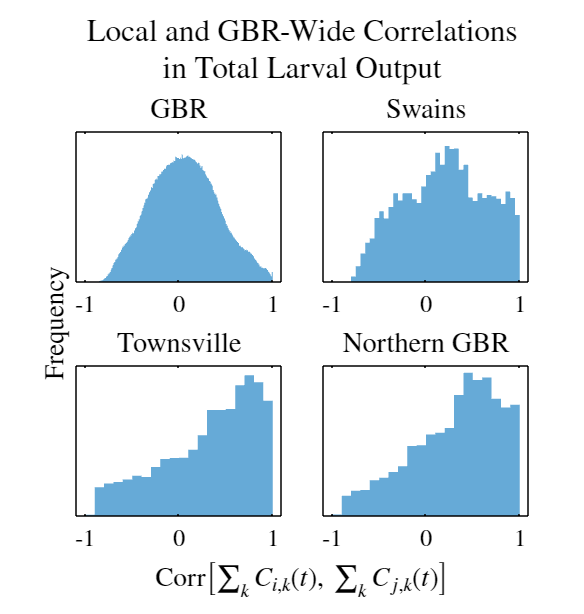

figure
var1 = plotConnectivityStats({corrMatCT(:), corrMatSwains(:), corrMatTowns(:), ...
    corrMatNorth(:),}, "correlationLoc", ["GBR", "Swains", ...
    "Townsville", "Northern GBR"], "pres");
for i = 1:length(var1)
    set(var1(i),'YTickLabel',[]);
    var1(i).YAxis.TickLength = [0 0];
end
setFontSize(20)
figResize(1.4)
lightFig()
saveFig("connectivityCorrLocPP")

## Proportional Overlap Between Simulations

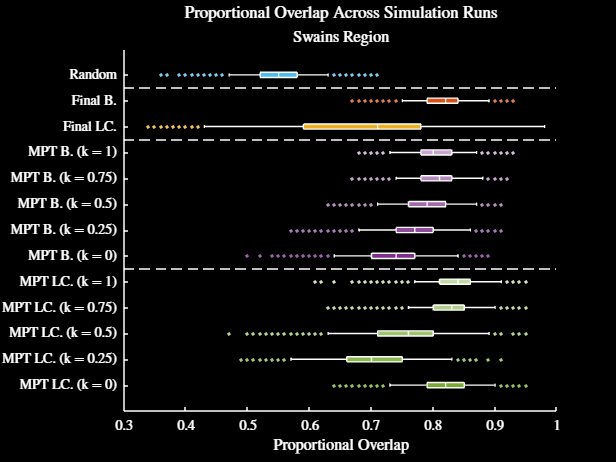

% going to look at the proportional overlap between solutions from the same
% decision-making methods
figure
plotOverlapProps(simOutCellSwains, [], "Swains", "intra", ...
    false)
setFontSize(12)
saveFig("propOverlapIntraSwains")
plotOverlapProps(simOutCellSwains, [], "Swains", "intra", ...
    true)
darkFig()
setFontSize(12)
saveFig("propOverlapIntraSwainsDM")

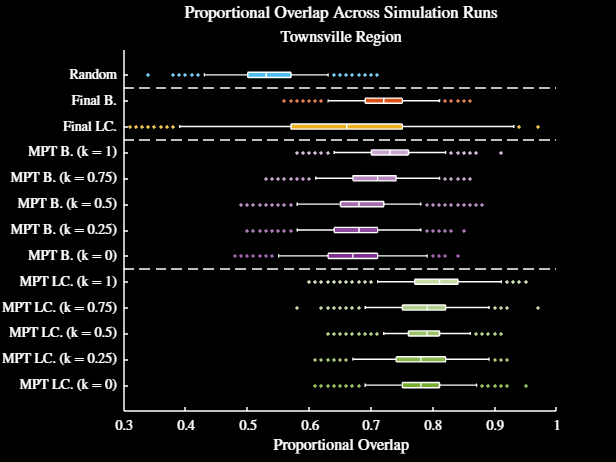

% do the same for the Townsville area
figure
plotOverlapProps(simOutCellTowns, [], "Townsville", "intra", ...
    false)
setFontSize(12)
saveFig("propOverlapIntraTowns")
plotOverlapProps(simOutCellTowns, [], "Townsville", "intra", ...
    true)
darkFig()
setFontSize(12)
saveFig("propOverlapIntraTownsDM")

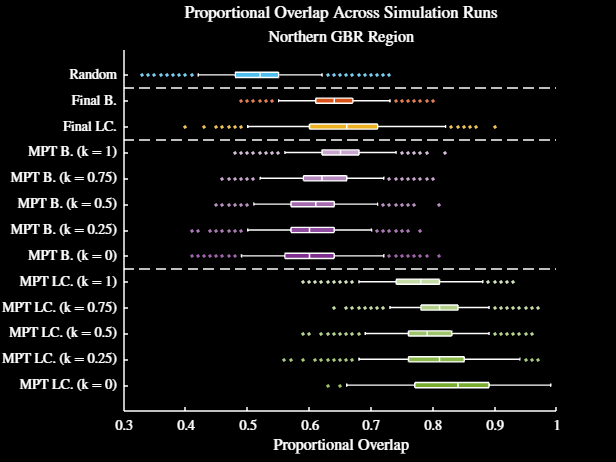

% do the same for the North area
figure
plotOverlapProps(simOutCellNorth, [], "Northern GBR", "intra", ...
    false)
setFontSize(12)
saveFig("propOverlapIntraNorth")
plotOverlapProps(simOutCellNorth, [], "Northern GBR", "intra", ...
    true)
darkFig()
setFontSize(12)
saveFig("propOverlapIntraNorthDM")

## Spatial Spread of Solutions

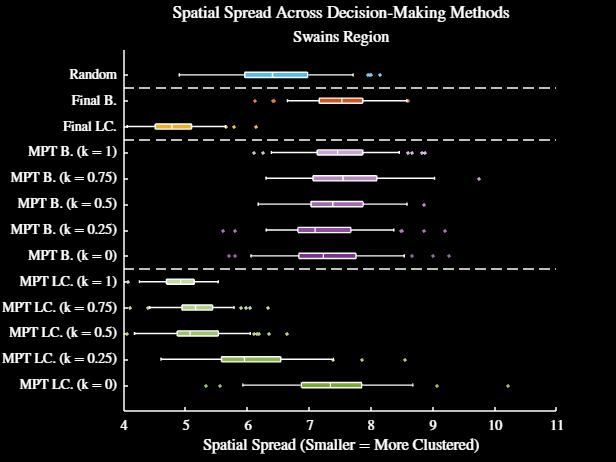

% now gonna look at the spatial spread of these solutions
figure
plotSpatialSpread(simOutCellSwains, GBRShapeSwains, "Swains", ...
    false)
setFontSize(12)
saveFig("spatialSpreadSwains")
plotSpatialSpread(simOutCellSwains, GBRShapeSwains, "Swains", ...
    true)
darkFig()
setFontSize(12)
saveFig("spatialSpreadSwainsDM")

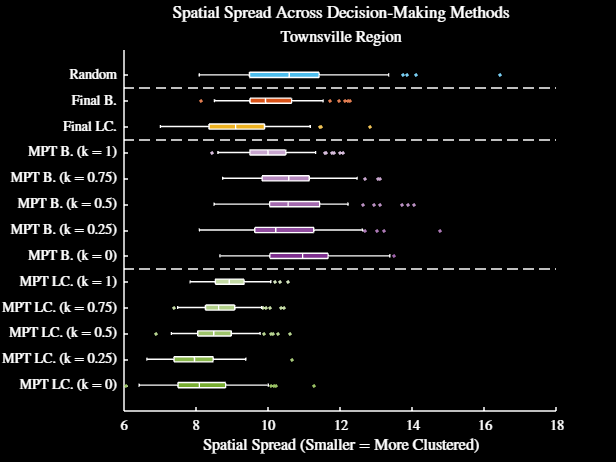

figure
plotSpatialSpread(simOutCellTowns, GBRShapeTowns, "Townsville", ...
    false)
setFontSize(12)
saveFig("spatialSpreadTowns")
plotSpatialSpread(simOutCellTowns, GBRShapeTowns, "Townsville", ...
    true)
darkFig()
setFontSize(12)
saveFig("spatialSpreadTownsDM")

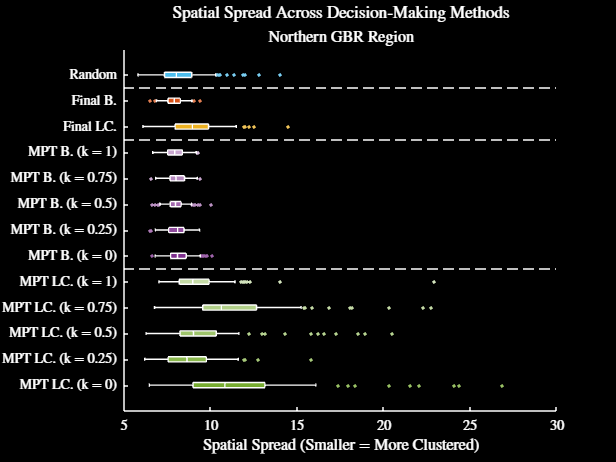

figure
plotSpatialSpread(simOutCellNorth, GBRShapeNorth, "Northern GBR", ...
    false)
setFontSize(12)
saveFig("spatialSpreadNorth")
plotSpatialSpread(simOutCellNorth, GBRShapeNorth, "Northern GBR", ...
    true)
darkFig()
setFontSize(12)
saveFig("spatialSpreadNorthDM")

## Solution Heatmaps

% fuck me dead I gotta do this bullshit
% modInds = 5:9;
% figure
% plotSelectionHeatmap(simOutCellSwains, modInds, "Swains", GBRShapeSwains)
% figResize(2.5, 1.3)
% saveFig("selFreqHeatmapSwainsBiom")
% darkFig()
% saveFig("selFreqHeatmapSwainsBiomDM")
% 
% modInds = 10:14;
% figure
% plotSelectionHeatmap(simOutCellSwains, modInds, "Swains", GBRShapeSwains)
% figResize(2.5, 1.3)
% saveFig("selFreqHeatmapSwainsLC")
% darkFig()
% saveFig("selFreqHeatmapSwainsLCDM")

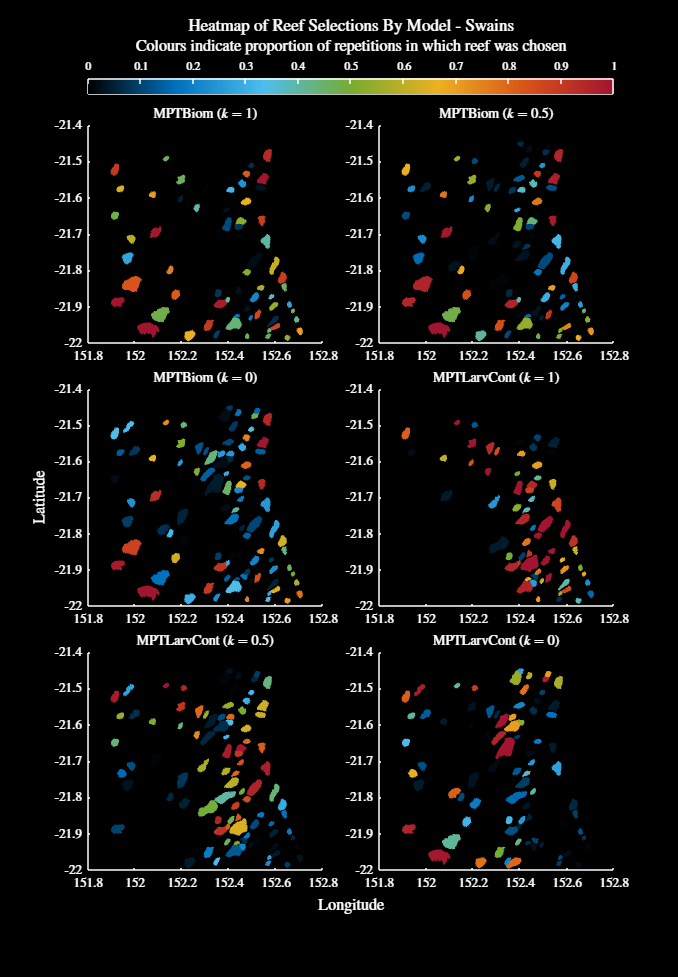

modInds = [5, 7, 9, 10, 12, 14];
figure
plotSelectionHeatmap(simOutCellSwains, modInds, "Swains", GBRShapeSwains)
figResize(2.5, 1.3)
saveFig("selFreqHeatmapSwains")
darkFig()
saveFig("selFreqHeatmapSwainsDM")

% do the same for the Townsville area
% modInds = 5:9;
% figure
% plotSelectionHeatmap(simOutCellTowns, modInds, "Townsville", GBRShapeTowns)
% figResize(2.5, 1.3)
% saveFig("selFreqHeatmapTownsBiom")
% darkFig()
% saveFig("selFreqHeatmapTownsBiomDM")
% 
% modInds = 10:14;
% figure
% plotSelectionHeatmap(simOutCellTowns, modInds, "Townsville", GBRShapeTowns)
% figResize(2.5, 1.3)
% saveFig("selFreqHeatmapTownsLC")
% darkFig()
% saveFig("selFreqHeatmapTownsLCDM")

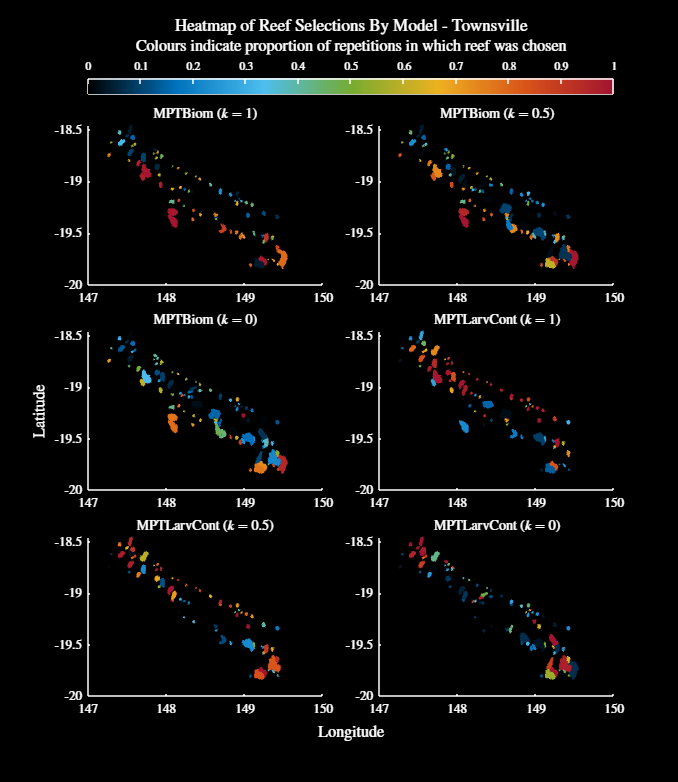

modInds = [5, 7, 9, 10, 12, 14];
figure
plotSelectionHeatmap(simOutCellTowns, modInds, "Townsville", GBRShapeTowns)
figResize(2, 1.3)
saveFig("selFreqHeatmapTowns")
darkFig()
saveFig("selFreqHeatmapTownsDM")

% modInds = 5:9;
% figure
% plotSelectionHeatmap(simOutCellNorth, modInds, "Northern GBR", GBRShapeNorth)
% figResize(2.5, 1.3)
% saveFig("selFreqHeatmapNorthBiom")
% darkFig()
% saveFig("selFreqHeatmapNorthBiomDM")
% 
% modInds = 10:14;
% figure
% plotSelectionHeatmap(simOutCellNorth, modInds, "Northern GBR", GBRShapeNorth)
% figResize(2.5, 1.3)
% saveFig("selFreqHeatmapNorthLC")
% darkFig()
% saveFig("selFreqHeatmapNorthLCDM")

modInds = [5, 7, 9, 10, 12, 14];
figure
plotSelectionHeatmap(simOutCellNorth, modInds, "Northern GBR", GBRShapeNorth)
figResize(2.25)
saveFig("selFreqHeatmapNorth")
darkFig()
saveFig("selFreqHeatmapNorthDM")

## Patterns in Solutions

simOutCellSwains{3}.methodStruct.methodInd

ans = "finalBiom"

simOutCellSwains{5}.methodStruct.methodInd

ans = "MPTBiom"

simOutCellSwains{5}.methodStruct.meanVarWeight

ans = 1

simOutCellSwains{14}.methodStruct.methodInd

ans = "MPTLarvCont"

simOutCellSwains{14}.methodStruct.meanVarWeight

ans = 0

% this is gonna be fucked I think tbh
% figure
% plotSelections(simOutCellTowns{3}, 1:10, "Towns", GBRShapeTowns)
% figResize(4, 1.3)
% darkFig()
% saveFig("spatialPatterningsTowns")

simOutCellNorth

simOutCellNorth = 1×14 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


## CV Values for Simulated Metapopulations

% look at metapopulation CVs, across the entire GBR maybe if I have time

## Penis shit fuck

simOutCellSwains{1}.mpaSel{1}

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


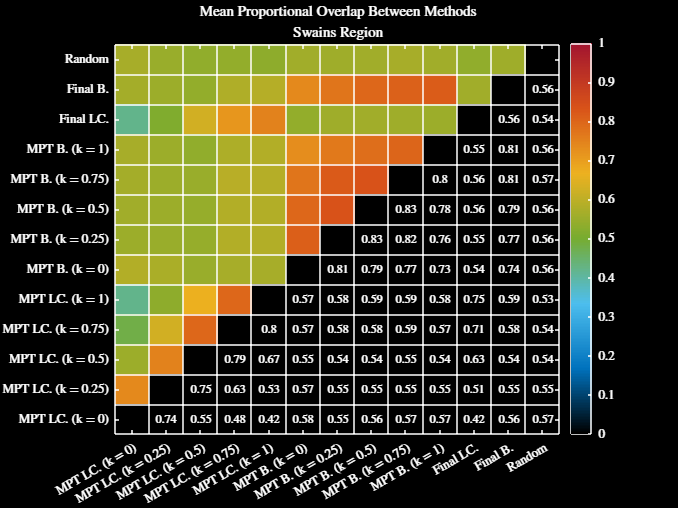

% going to look at the proportional overlap between solutions from the same
% decision-making methods
figure
plotOverlapProps(simOutCellSwains, [], "Swains", "inter")
setFontSize(11)
figResize(1.1, 1.1)
saveFig("propOverlapInterSwains")
darkFig()
saveFig("propOverlapInterSwainsDM")

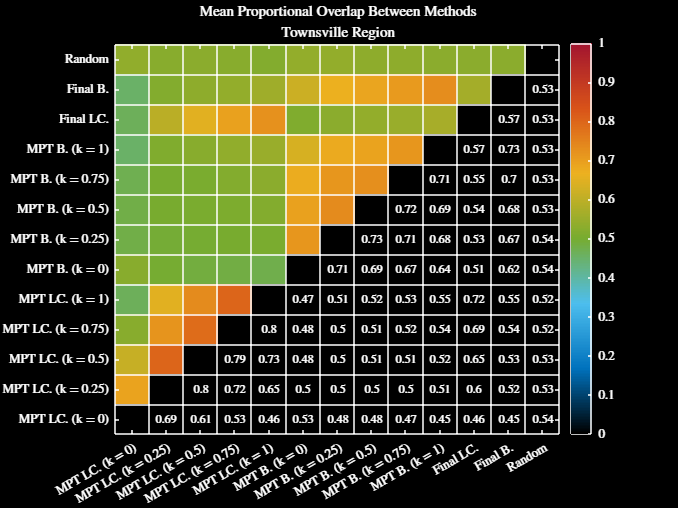

% do the same for the Townsville area
figure
plotOverlapProps(simOutCellTowns, [], "Townsville", "inter")
setFontSize(11)
figResize(1.1, 1.1)
saveFig("propOverlapInterTowns")
darkFig()
saveFig("propOverlapInterTownsDM")

% do the same for the North area
figure
plotOverlapProps(simOutCellNorth, [], "Northern GBR", "inter")

Unrecognized function or variable 'simOutCellNorth'.

setFontSize(11)
figResize(1.1, 1.1)
saveFig("propOverlapInterNorth")
darkFig()
saveFig("propOverlapInterNorthDM")